# Powertrain simulation

## Output power initialization

restoredefaultpath;
currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
        (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
        ~isempty(currentfolder{end}))
currentpath = fileparts(currentpath);
currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath));
clear projectpath currentpath currentfolder

load load_to_test_2
old_w = str2double(to_try.power)';
old_t = str2double(to_try.time)'/2;
t = 0:1e-3:old_t(end);
w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');
clear old_w old_t to_try XTest YTest

## Test sources model vs simple resistance

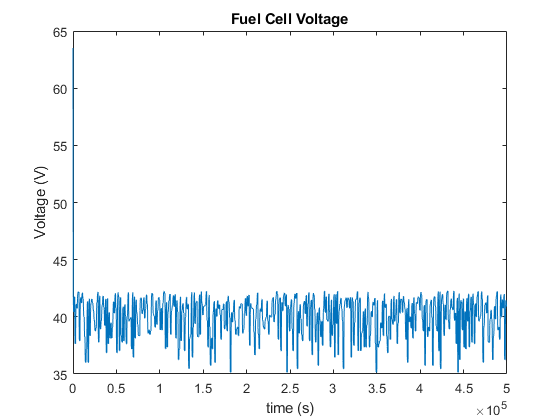

Ts = 1e-3; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts); % init data sources % SOC set at 80
SimTime = 500; % Max simulation time
Ifc = 0.001;
Ibatt = 0;
Res = 6.09;
Res_batt = 2;
power_fc = zeros(1,SimTime/Ts);
current_fc = zeros(1,SimTime/Ts);
voltage_fc = zeros(1,SimTime/Ts);
power_batt = zeros(1,SimTime/Ts);
current_batt = zeros(1,SimTime/Ts);
voltage_batt = zeros(1,SimTime/Ts);
soc_batt = zeros(1,SimTime/Ts);
time_vector = 0:1:SimTime/Ts-1;
for i=1:1:SimTime/Ts
    %     sprintf("sample : %.0f", i/Ts)
    
    % part sim model
    [FCdata] = fuel_cell_model(Ifc,FCdata);
    [BATTdata] = battery_model(Ibatt,BATTdata);
    
    %     if i == 5
    %         Res = 100;
    %     end
    %     Res = i*Ts+1413*Ts;
    %     if i*Ts > 30
    %         Res = randi(100);
    %     end
    if ~mod(i*Ts,1)
        Res = 1.313 + randi(100)/10;
    end
    
    
    
    %% fc
    % current
    Ifc = FCdata.Efc/Res;
    
    % arrays
    voltage_fc(i) = FCdata.Efc;
    current_fc(i) = Ifc;
    power_fc(i) = Ifc*FCdata.Efc;
    
    if ~mod(i*Ts,1)
        Res_batt = max(2,Res);
        if randi(2) == 1
            Res_batt = -randi(25)/5- 20;
        end
    end
    
    %% batt
    % current
    Ibatt = BATTdata.voltage/(BATTdata.R+Res_batt);
    BATTdata.ouput_voltage = BATTdata.voltage*Res_batt/(BATTdata.R+Res_batt);
    
    % arrays
    voltage_batt(i) = BATTdata.ouput_voltage;
    current_batt(i) = Ibatt;
    power_batt(i) = abs(BATTdata.ouput_voltage)*Ibatt;
    soc_batt(i) = BATTdata.SOC;
end

new_plot(time_vector,voltage_fc,'Fuel Cell Voltage', 'time (s)', 'Voltage (V)')

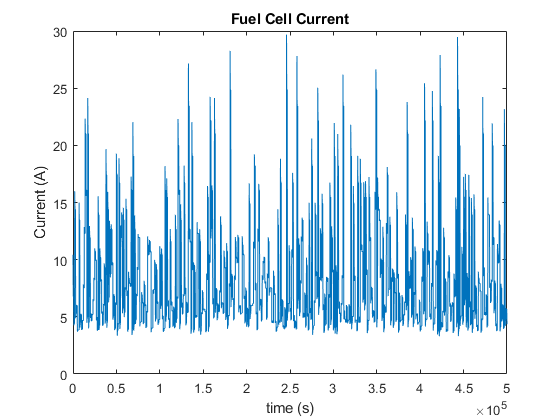

new_plot(time_vector,current_fc,'Fuel Cell Current', 'time (s)', 'Current (A)')

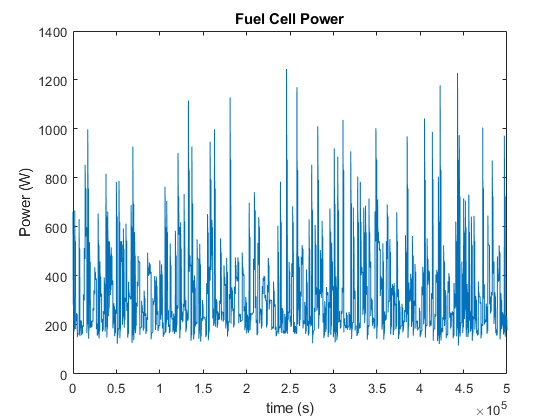

new_plot(time_vector,power_fc,'Fuel Cell Power', 'time (s)', 'Power (W)')

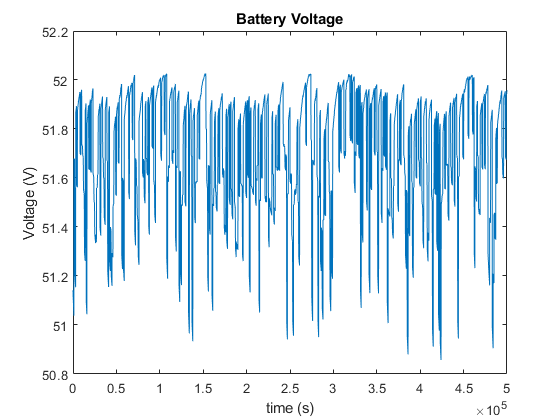


new_plot(time_vector,voltage_batt,'Battery Voltage', 'time (s)', 'Voltage (V)')

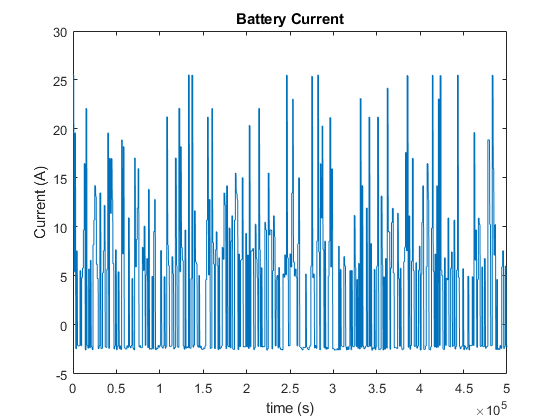

new_plot(time_vector,current_batt,'Battery Current', 'time (s)', 'Current (A)')

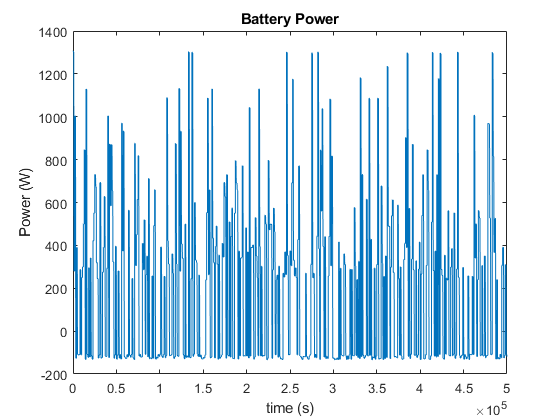

new_plot(time_vector,power_batt,'Battery Power', 'time (s)', 'Power (W)')

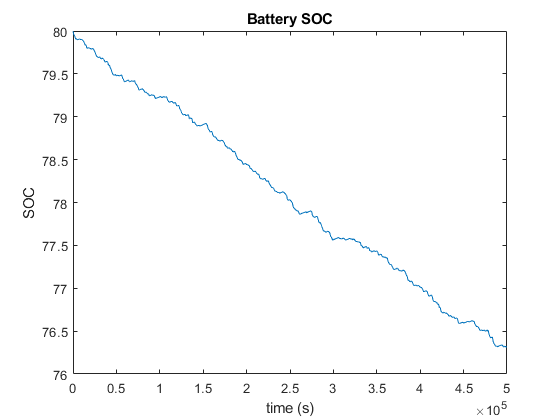

new_plot(time_vector,soc_batt,'Battery SOC', 'time (s)', 'SOC')


mdl_ifc = fitlm(power_fc,current_fc); % current depending on the power(t)
X = [power_batt(1:1:end); soc_batt(1:1:end)]';
mdl_ibatt = fitlm(X,current_batt(1:1:end)); % current depending on soc(t) and power(t)
% feval(mdl_ibatt,power_batt(1:1:end),soc_batt(1:1:end)); % to use
mdl_dsoc = fitlm(power_batt(1:end-1),diff(soc_batt));
[80+feval(mdl_dsoc,power_batt(1)) soc_batt(2) (80+feval(mdl_dsoc,power_batt(1)))/soc_batt(2)]

ans =   79.999952786532035  79.999952646468259   1.000000001750798


## Powertrain simulation

Ts = 1e-3; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts); % init data sources % SOC set at 80
SimTime = 100; % Max simulation time
Vdc_wanted = 72;
Ifc = 0.001;
Ibatt = 0;
Res_fc = w(1);
Res_batt = w(1);
power_fc = zeros(1,SimTime/Ts);
current_fc = zeros(1,SimTime/Ts);
voltage_fc = zeros(1,SimTime/Ts);
power_batt = zeros(1,SimTime/Ts);
current_batt = zeros(1,SimTime/Ts);
voltage_batt = zeros(1,SimTime/Ts);
soc_batt = zeros(1,SimTime/Ts);
test = zeros(1,SimTime/Ts);
Ppv_out = 140;
time_vector = 1:Ts:SimTime;
for i=1:1:SimTime/Ts
    %     sprintf("sample : %.0f", i/Ts)
    
    % part sim model
    if w(i+1)-Ppv_out > 0
        [FCdata] = fuel_cell_model(Ifc,FCdata);
        %         Res_fc = min(Vdc_wanted^2/((w(i)-Ppv_out)/0.9),min(10000,FCdata.Efc^2/((w(i+1)-Ppv_out)/0.9)));
        Ifc = ((w(i)-Ppv_out)/0.9)/FCdata.Efc;
    end
    [BATTdata] = battery_model(Ibatt,BATTdata);
    
    Res_batt = (BATTdata.voltage ^2)/((w(i)-Ppv_out)/0.9)-BATTdata.R;
    %     Res_batt = (BATTdata.voltage ^2)/((w(i)-Ppv_out)/0.9)-BATTdata.R;
    
    %% fc
    % current
    %     Ifc = FCdata.Efc/Res;
    
    % arrays
    voltage_fc(i) = FCdata.Efc;
    current_fc(i) = Ifc;
    power_fc(i) = Ifc*FCdata.Efc;
    
    
    %% batt
    % current
    Ibatt = BATTdata.voltage/(BATTdata.R+Res_batt);
    BATTdata.ouput_voltage = BATTdata.voltage*Res_batt/(BATTdata.R+Res_batt);
    
    % arrays
    voltage_batt(i) = BATTdata.ouput_voltage;
    current_batt(i) = Ibatt;
    power_batt(i) = BATTdata.ouput_voltage*Ibatt;
    soc_batt(i) = BATTdata.SOC;
end

new_plot(time_vector,voltage_fc,'Fuel Cell Voltage', 'time (s)', 'Voltage (V)')
new_plot(time_vector,current_fc,'Fuel Cell Current', 'time (s)', 'Current (A)')
new_plot(time_vector,power_fc,'Fuel Cell Power', 'time (s)', 'Power (W)')

new_plot(time_vector,voltage_batt,'Battery Voltage', 'time (s)', 'Voltage (V)')
new_plot(time_vector,current_batt,'Battery Current', 'time (s)', 'Current (A)')
new_plot(time_vector,power_batt,'Battery Power', 'time (s)', 'Power (W)')
new_plot(time_vector,soc_batt,'Battery SOC', 'time (s)', 'SOC')

### Test without FC model

Ts = 1e-3; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts); % init data sources % SOC set at 80
SimTime = t(end); % Max simulation time
Vdc_wanted = 72;
Ifc = 0.001;
Ibatt = 0;
Res_fc = w(1);
Res_batt = w(1);
power_fc = zeros(1,SimTime/Ts);
current_fc = zeros(1,SimTime/Ts);
voltage_fc = zeros(1,SimTime/Ts);
power_batt = zeros(1,SimTime/Ts);
current_batt = zeros(1,SimTime/Ts);
voltage_batt = zeros(1,SimTime/Ts);
soc_batt = zeros(1,SimTime/Ts);
test = zeros(1,SimTime/Ts);
Pfc = 0;
Ppv_out = 140;
Pout = w(1:Ts/1e-3:SimTime/1e-3);
time_vector = 0:Ts:SimTime-Ts;
tic
for i=1:1:SimTime/Ts
    %         sprintf("sample : %.0f", i/Ts)
    [BATTdata] = battery_model(Ibatt,BATTdata);
    
    Pout_required = Pout(i)-Ppv_out;
    if Pout_required > 0 && ~mod(i,1/Ts)
        [Pfc, Pbatt] = EEDMS_func(BATTdata.SOC,Pout_required,Pfc,Ts);
        %         sprintf("sample : %.0f", i*Ts)
    else
        if Pout_required < 0
            Pfc = 0;
        end
        Pbatt = Pout_required-Pfc;
    end
    
    % arrays
    power_fc(i) = Pfc;
    
    
    %% batt
    Res_batt = (BATTdata.voltage ^2)/Pbatt-BATTdata.R;
    
    % current
    Ibatt = BATTdata.voltage/(BATTdata.R+Res_batt);
    BATTdata.ouput_voltage = BATTdata.voltage*Res_batt/(BATTdata.R+Res_batt);
    
    % arrays
    voltage_batt(i) = BATTdata.ouput_voltage;
    current_batt(i) = Ibatt;
    power_batt(i) = BATTdata.ouput_voltage*Ibatt;
    soc_batt(i) = BATTdata.SOC;
end
toc

Elapsed time is 103.498574 seconds.


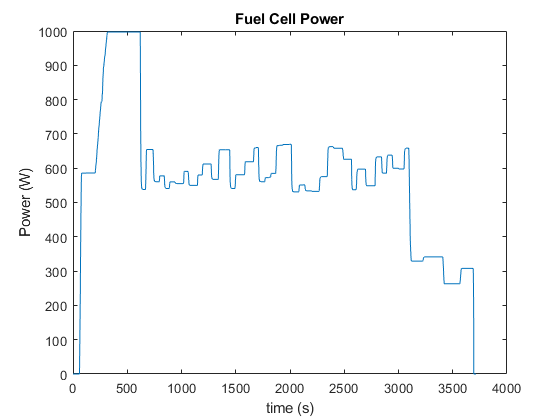

new_plot(time_vector,power_fc,'Fuel Cell Power', 'time (s)', 'Power (W)')

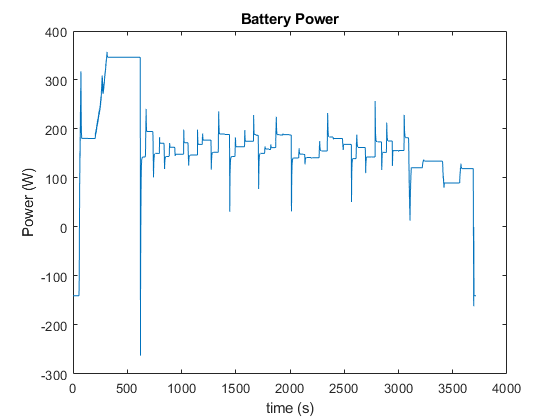


% new_plot(time_vector,voltage_batt,'Battery Voltage', 'time (s)', 'Voltage (V)')
% new_plot(time_vector,current_batt,'Battery Current', 'time (s)', 'Current (A)')
new_plot(time_vector,power_batt,'Battery Power', 'time (s)', 'Power (W)')

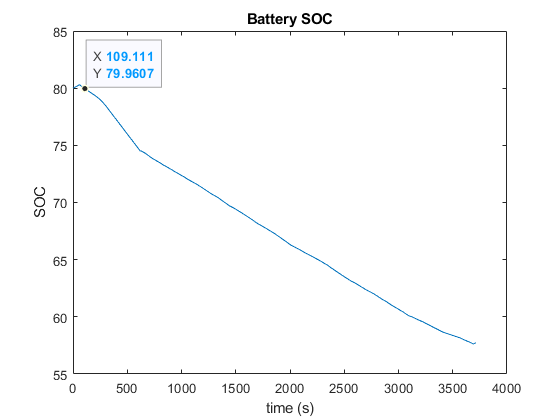

new_plot(time_vector,soc_batt,'Battery SOC', 'time (s)', 'SOC')

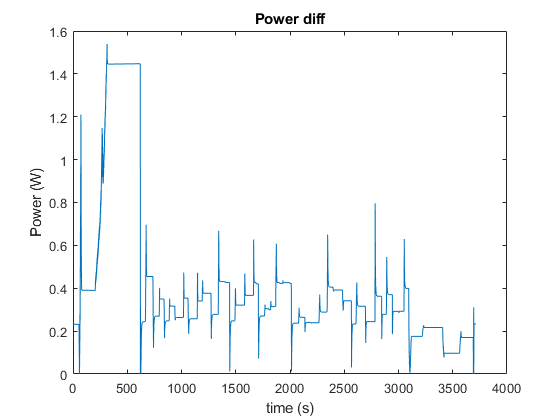


new_plot(time_vector,Pout-Ppv_out-(power_batt+power_fc),'Power diff', 'time (s)', 'Power (W)');

% dsoc_bis = -current_batt(1:end)*100*Ts/(3600*BATTdata.Qc*BATTdata.lambda)*1.069155999963626;
mdl_dsoc = fitlm(power_batt(1:end-1),diff(soc_batt));
% feval(mdl_dsoc,1); % to use

### Dynamic Programming Backward

Ts = 1; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts); % init data sources % SOC set at 80
SimTime = t(end); % Max simulation time
power_fc_dp = zeros(1,SimTime/Ts);
power_batt_dp = zeros(1,SimTime/Ts);
soc_batt_dp = zeros(1,SimTime/Ts);
dsoc_dp = feval(mdl_dsoc,-200:0.01:1200);
soc_0 = soc_batt(1);
soc_f = soc_batt(end);
soc = 20:1:90;
max_soc = 90;
min_soc = 20;
time_vector = 0:Ts:SimTime-Ts;
dPfc = 100;
Pfc_max = 1100;
Pfc_min = 0;
Ppv_out = 140;
% Pout = w(610e3+1:Ts/1e-3:630/1e-3);
Pout = w(1:Ts/1e-3:SimTime/1e-3);
fc_power_array = zeros(length(soc),SimTime/Ts);
fc_power_array(:,end)=min(Pfc_max,max(Pfc_min,Pout(end)));
Pbatt_max = 1000;
Pbatt_min = -200;
global_cost = zeros(length(soc),SimTime/Ts);
batt_power_array = zeros(length(soc),SimTime/Ts);
old_fc_func = zeros(length(soc),SimTime/Ts);
old_batt_func = zeros(length(soc),SimTime/Ts);
old_h2_func = zeros(length(soc),SimTime/Ts);
tStart = tic;
tic
for i=SimTime/Ts-1:-1:1
    for j=1:length(soc)
        Pout_required = Pout(i)-Ppv_out;
        
        %         % old
        %         ubPfc = min([Pfc_max]);
        %         lbPfc = max([Pfc_min]);
        %         Pfc_grid = linspace(lbPfc,ubPfc,101); % fuel cell power grid
        %         Pbatt_grid = Pout_required/0.9 - Pfc_grid;
        %         Pbatt_grid = min(1000,max(-200,Pbatt_grid));
        %
        %         dsoc_grid = 1e3/Ts*feval(mdl_dsoc,Pbatt_grid); % delta soc grid (possible)
        %         soc_grid = soc(j) - dsoc_grid; % next soc possible
        %         next_soc_index = closest_value(soc,soc_grid); % next soc possible
        %         next_Pfc = fc_power_array(next_soc_index,i+1)';
        %
        %         Ifc_in = feval(mdl_ifc,Pfc_grid); % function of Pfc
        %         Ibatt_in = feval(mdl_ibatt,Pbatt_grid,soc_grid); % function of Pbatt and SOC
        %
        %         [gcf,new_fc_func,new_batt_func,new_h2_func] = one_global_cost_function(0,SimTime/Ts-i,...
        %             Pfc_grid,Ifc_in,Ibatt_in,soc_grid,old_fc_func(j,i+1),old_batt_func(j,i+1),...
        %             old_h2_func(j,i+1),SimTime/Ts-i);  % global cost function calculation for all the different soc
        %
        %         %         lcf = 0;
        %         lcf = local_cost_function_2(Pfc_grid,soc_grid,zeros(1,length(soc_grid))+soc(j),next_Pfc);
        %
        %         [global_cost(j,i), k] = min([gcf + lcf]);
        %         batt_power_array(j,i) = Pbatt_grid(k);
        %         fc_power_array(j,i) = Pfc_grid(k);
        %         old_fc_func(j,i) = old_fc_func(j,i+1) + new_fc_func(k);
        %         old_batt_func(j,i) = old_batt_func(j,i+1) + new_batt_func(k);
        %         old_h2_func(j,i) = old_h2_func(j,i+1) + new_h2_func(k);
        
        % new
        Pbatt_grid = linspace(-200,1000,141);
        
        dsoc_grid = 1e3/Ts*feval(mdl_dsoc,Pbatt_grid); % delta soc grid (possible)
        soc_grid = soc(j) + dsoc_grid;
        ind_range = find(soc_grid<min_soc | soc_grid>max_soc); % del soc / Pbatt not in range
        soc_grid(ind_range) = [];
        Pbatt_grid(ind_range) = [];
        
        next_soc_index = closest_value(soc,soc_grid); % next soc possible
        next_Pfc = fc_power_array(next_soc_index,i+1)'; % next pfc based on soc possible
        ubPfc = min(zeros(1,length(next_Pfc))+Pfc_max, next_Pfc+dPfc); % upper
        lbPfc = max(zeros(1,length(next_Pfc))+Pfc_min, next_Pfc-dPfc); % lower bound for PFC
        Pfc_grid = min(ubPfc,max(lbPfc,(Pout_required/0.9-Pbatt_grid))); % Pfc grid based on next value and soc
        Pbatt_grid = Pout_required/0.9-Pfc_grid; % rearrange Pbatt
        
        
        Ifc_in = feval(mdl_ifc,Pfc_grid); % function of Pfc
        Ibatt_in = feval(mdl_ibatt,Pbatt_grid,soc_grid); % function of Pbatt and SOC
        
        [gcf,new_fc_func,new_batt_func,new_h2_func] = one_global_cost_function(0,SimTime/Ts-i,...
            Pfc_grid,Ifc_in,Ibatt_in,soc_grid,old_fc_func(next_soc_index,i+1)',old_batt_func(next_soc_index,i+1)',...
            old_h2_func(next_soc_index,i+1)',SimTime/Ts-i);  % global cost function calculation for all the different soc
        
        %                 lcf = 0;
        %         lcf = local_cost_function(Pfc_grid,soc_grid,Pbatt_grid,Ts);
        lcf = local_cost_function_2(Pfc_grid,soc_grid,zeros(1,length(soc_grid))+soc(j),next_Pfc);
        
        [global_cost(j,i), k] = min([gcf + lcf]);
        batt_power_array(j,i) = Pbatt_grid(k);
        fc_power_array(j,i) = Pfc_grid(k);
        old_fc_func(j,i) = old_fc_func(next_soc_index(k),i+1) + new_fc_func(k);
        old_batt_func(j,i) = old_batt_func(next_soc_index(k),i+1) + new_batt_func(k);
        old_h2_func(j,i) = old_h2_func(next_soc_index(k),i+1) + new_h2_func(k);
    end
    if ~mod(i,100)
        toc
        sprintf("sample : %.0f", i)
        tic
    end
end

Elapsed time is 10.529933 seconds.


ans = "sample : 3700"

Elapsed time is 74.274871 seconds.


ans = "sample : 3600"

Elapsed time is 74.226354 seconds.


ans = "sample : 3500"

Elapsed time is 74.364884 seconds.


ans = "sample : 3400"

Elapsed time is 74.329851 seconds.


ans = "sample : 3300"

Elapsed time is 74.660920 seconds.


ans = "sample : 3200"

Elapsed time is 76.300735 seconds.


ans = "sample : 3100"

Elapsed time is 74.143241 seconds.


ans = "sample : 3000"

Elapsed time is 74.484955 seconds.


ans = "sample : 2900"

Elapsed time is 74.277547 seconds.


ans = "sample : 2800"

Elapsed time is 74.037783 seconds.


ans = "sample : 2700"

Elapsed time is 74.086809 seconds.


ans = "sample : 2600"

Elapsed time is 73.993927 seconds.


ans = "sample : 2500"

Elapsed time is 74.029124 seconds.


ans = "sample : 2400"

Elapsed time is 74.260231 seconds.


ans = "sample : 2300"

Elapsed time is 74.045896 seconds.


ans = "sample : 2200"

Elapsed time is 74.146542 seconds.


ans = "sample : 2100"

Elapsed time is 74.194235 seconds.


ans = "sample : 2000"

Elapsed time is 74.044182 seconds.


ans = "sample : 1900"

Elapsed time is 74.027706 seconds.


ans = "sample : 1800"

Elapsed time is 74.260831 seconds.


ans = "sample : 1700"

Elapsed time is 73.952527 seconds.


ans = "sample : 1600"

Elapsed time is 74.512753 seconds.


ans = "sample : 1500"

Elapsed time is 74.019236 seconds.


ans = "sample : 1400"

Elapsed time is 74.188275 seconds.


ans = "sample : 1300"

Elapsed time is 74.176687 seconds.


ans = "sample : 1200"

Elapsed time is 74.218235 seconds.


ans = "sample : 1100"

Elapsed time is 74.201407 seconds.


ans = "sample : 1000"

Elapsed time is 74.226289 seconds.


ans = "sample : 900"

Elapsed time is 74.296630 seconds.


ans = "sample : 800"

Elapsed time is 74.454828 seconds.


ans = "sample : 700"

Elapsed time is 74.328011 seconds.


ans = "sample : 600"

Elapsed time is 74.326198 seconds.


ans = "sample : 500"

Elapsed time is 74.202753 seconds.


ans = "sample : 400"

Elapsed time is 74.175038 seconds.


ans = "sample : 300"

Elapsed time is 73.950086 seconds.


ans = "sample : 200"

Elapsed time is 74.040779 seconds.


ans = "sample : 100"

toc

Elapsed time is 73.249316 seconds.


toc(tStart)

Elapsed time is 2757.457373 seconds.


#### Test DP

Ts = 1e-3; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts); % init data sources % SOC set at 80
% SimTime = t(end); % Max simulation time
Vdc_wanted = 72;
Ifc = 0.001;
Ibatt = 0;
Res_fc = w(1);
Res_batt = w(1);
power_fc = zeros(1,SimTime/Ts);
current_fc = zeros(1,SimTime/Ts);
voltage_fc = zeros(1,SimTime/Ts);
power_batt = zeros(1,SimTime/Ts);
current_batt = zeros(1,SimTime/Ts);
voltage_batt = zeros(1,SimTime/Ts);
soc_batt = zeros(1,SimTime/Ts);
test = zeros(1,SimTime/Ts);
Pfc = 0;
Ppv_out = 140;
Pout = w(1:Ts/1e-3:SimTime/1e-3);
% Pout = w(610e3+1:Ts/1e-3:630/1e-3);
time_vector = 0:Ts:SimTime-Ts;
tic
for i=1:1:SimTime/Ts
    %         sprintf("sample : %.0f", i/Ts)
    [BATTdata] = battery_model(Ibatt,BATTdata);
    [FCdata] = fuel_cell_model(Ifc,FCdata);
    
    Pout_required = Pout(i)-Ppv_out;
    if i > 1 && ~mod(i,1e3)
        [value,index] = min(abs(soc-BATTdata.SOC));
        Pfc = max(0,min(1100,fc_power_array(index,i/1e3)));
        % Pbatt = max(-200,min(1000,batt_power_array(index,i/1e3)));
        % Pfc = Pout_required - Pbatt;
    end
    Pbatt = Pout_required - Pfc;
    
    
    
    Ifc = Pfc/FCdata.Efc;
    
    % arrays
    voltage_fc(i) = FCdata.Efc;
    current_fc(i) = Ifc;
    power_fc(i) = Ifc*FCdata.Efc;
    
    
    %% batt
    Res_batt = (BATTdata.voltage ^2)/Pbatt-BATTdata.R;
    
    % current
    Ibatt = BATTdata.voltage/(BATTdata.R+Res_batt);
    BATTdata.ouput_voltage = BATTdata.voltage*Res_batt/(BATTdata.R+Res_batt);
    
    % arrays
    voltage_batt(i) = BATTdata.ouput_voltage;
    current_batt(i) = Ibatt;
    power_batt(i) = BATTdata.ouput_voltage*Ibatt;
    soc_batt(i) = BATTdata.SOC;
end
toc

Elapsed time is 143.637072 seconds.


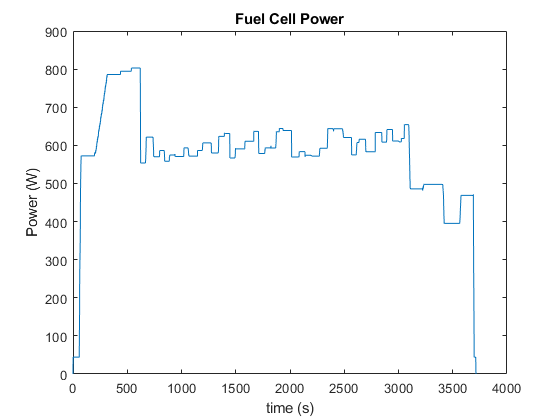

new_plot(time_vector,power_fc,'Fuel Cell Power', 'time (s)', 'Power (W)')

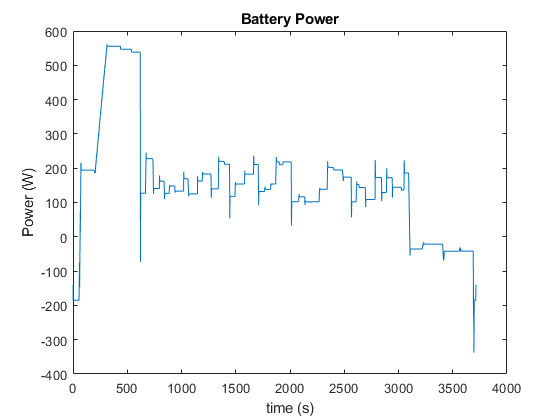

new_plot(time_vector,power_batt,'Battery Power', 'time (s)', 'Power (W)')

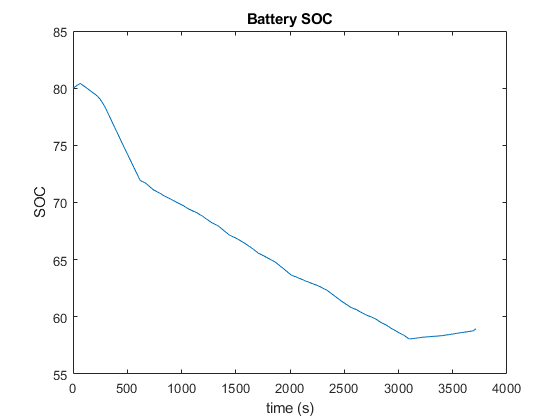

new_plot(time_vector,soc_batt,'Battery SOC', 'time (s)', 'SOC')

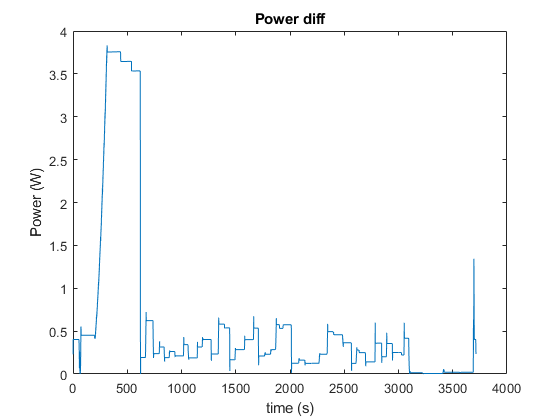

new_plot(time_vector,Pout-Ppv_out-(power_batt+power_fc),'Power diff', 'time (s)', 'Power (W)');


sum(local_cost_function(power_fc,soc_batt,power_batt,Ts)) % 1.5532e6

ans =      2.726050781476818e+06


global_cost_funciton(power_fc,current_fc,current_batt,soc_batt,time_vector) % without DeltaPfc 397.9367 % with 308.4196 % complete 1.3557e3 % % complete x 2  = 1.359e3

ans =            1     3714000


ans =            1     3714000


ans =      3.609190509614174e+02


% 360 in real